# ELM 极限学习机数据分类

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

clear; clc;
% 导入数据
load data_classification.mat
% 随机生成训练集、测试集
rng('default');
a = randperm(569);
% 训练集—500个样本
Train = data(a(1 : 500), :);
% 测试集—69个样本
Test = data(a(501 : end), :);
% 训练数据
P_train = Train(:, 3 : end)';
T_train = Train(:, 2)';
% 测试数据
P_test = Test(:, 3 : end)';
T_test = Test(:, 2)';
%% ELM
%  ELM创建、训练
[IW, B, LW, TF, TYPE] = ELMtrain(P_train, T_train, 100, 'sig', 1);
% ELM仿真测试
T_sim_1 = ELMpredict(P_train, IW, B, LW, TF, TYPE);
T_sim_2 = ELMpredict(P_test, IW, B, LW, TF, TYPE);
%% 结果对比
% 训练集正确率
k1 = length(find(T_train == T_sim_1));
n1 = length(T_train);
Accuracy_1 = k1 / n1 * 100;
disp(['训练集正确率Accuracy = ' num2str(Accuracy_1) '%(' num2str(k1) '/' num2str(n1) ')'])

训练集正确率Accuracy = 90.6%(453/500)


% 测试集正确率
k2 = length(find(T_test == T_sim_2));
n2 = length(T_test);
Accuracy_2 = k2 / n2 * 100;
disp(['测试集正确率Accuracy = ' num2str(Accuracy_2) '%(' num2str(k2) '/' num2str(n2) ')'])

测试集正确率Accuracy = 82.6087%(57/69)


%% 显示
count_B = length(find(T_train == 1));
count_M = length(find(T_train == 2));
total_B = length(find(data(:,2) == 1));
total_M = length(find(data(:,2) == 2));
number_B = length(find(T_test == 1));
number_M = length(find(T_test == 2));
number_B_sim = length(find(T_sim_2 == 1 & T_test == 1));
number_M_sim = length(find(T_sim_2 == 2 & T_test == 2));
disp(['病例总数：' num2str(569)  '  良性：' num2str(total_B)  '  恶性：' num2str(total_M)]);

病例总数：569  良性：357  恶性：212


disp(['训练集病例总数：' num2str(500) '  良性：' num2str(count_B) '  恶性：' num2str(count_M)]);

训练集病例总数：500  良性：316  恶性：184


disp(['测试集病例总数：' num2str(69) '  良性：' num2str(number_B) '  恶性：' num2str(number_M)]);

测试集病例总数：69  良性：41  恶性：28


disp(['良性乳腺肿瘤确诊：' num2str(number_B_sim) '  误诊：' num2str(number_B - number_B_sim) '  确诊率p1=' num2str(number_B_sim/number_B*100) '%']);

良性乳腺肿瘤确诊：37  误诊：4  确诊率p1=90.2439%


disp(['恶性乳腺肿瘤确诊：' num2str(number_M_sim) '  误诊：' num2str(number_M - number_M_sim) '  确诊率p2=' num2str(number_M_sim/number_M*100) '%']);

恶性乳腺肿瘤确诊：20  误诊：8  确诊率p2=71.4286%


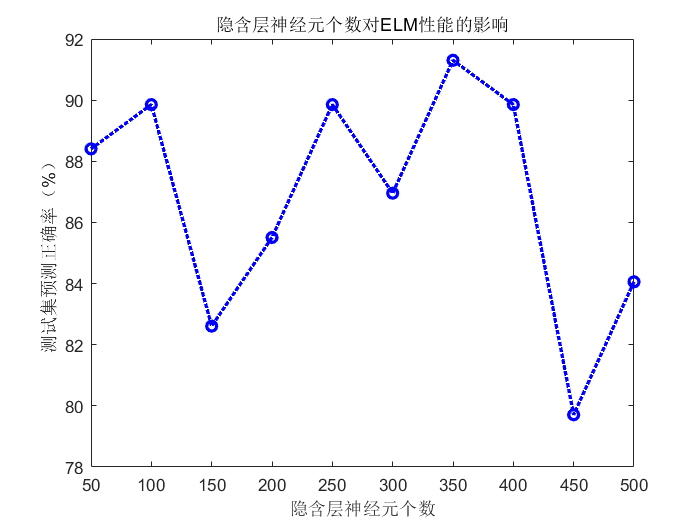

%%  隐含层神经元个数影响
R = zeros(10, 2);
for i = 1 : 10
    % ELM创建、训练
    [IW, B, LW, TF, TYPE] = ELMtrain(P_train, T_train, 50*i, 'sig', 1);
    % ELM仿真测试
    T_sim_1 = ELMpredict(P_train, IW, B, LW, TF, TYPE);
    T_sim_2 = ELMpredict(P_test, IW, B, LW, TF, TYPE);
    % 结果对比
    % 训练集正确率
    k1 = length(find(T_train == T_sim_1));
    n1 = length(T_train);
    Accuracy_1 = k1 / n1 * 100;
    % 测试集正确率
    k2 = length(find(T_test == T_sim_2));
    n2 = length(T_test);
    Accuracy_2 = k2 / n2 * 100;
    R(i, :) = [Accuracy_1 Accuracy_2];
end
plot(50*(1 : 10), R(:, 2), 'b:o', 'LineWidth', 2)
xlabel('隐含层神经元个数')
ylabel('测试集预测正确率（%）')
title('隐含层神经元个数对ELM性能的影响')

function [IW, B, LW, TF, TYPE] = ELMtrain(P, T, N, TF, TYPE)
%{
Input:
    P   - Input Matrix of Training Set  (R*Q)
    T   - Output Matrix of Training Set (S*Q)
    N   - Number of Hidden Neurons (default = Q)
    TF  - Transfer Function:
          'sig' for Sigmoidal function (default)
          'sin' for Sine function
          'hardlim' for Hardlim function
    TYPE - Regression (0, default) or Classification (1)
Output:
    IW  - Input Weight Matrix (N*R)
    B   - Bias Matrix  (N*1)
    LW  - Layer Weight Matrix (N*S)
%}
[R, Q] = size(P);
if TYPE  == 1
    T  = ind2vec(T);
end
% Randomly Generate the Input Weight Matrix
IW = rand(N, R) * 2 - 1;
% Randomly Generate the Bias Matrix
B = rand(N, 1);
BiasMatrix = repmat(B, 1, Q);
% Calculate the Layer Output Matrix H
tempH = IW * P + BiasMatrix;
switch TF
    case 'sig'
        H = 1 ./ (1 + exp(-tempH));
    case 'sin'
        H = sin(tempH);
    case 'hardlim'
        H = hardlim(tempH);
end
% Calculate the Output Weight Matrix
LW = pinv(H') * T';
end


function Y = ELMpredict(P, IW, B, LW, TF, TYPE)
%{
Input:
    P   - Input Matrix of Training Set  (R*Q)
    IW  - Input Weight Matrix (N*R)
    B   - Bias Matrix  (N*1)
    LW  - Layer Weight Matrix (N*S)
    TF  - Transfer Function:
          'sig' for Sigmoidal function (default)
          'sin' for Sine function
          'hardlim' for Hardlim function
    TYPE - Regression (0, default) or Classification (1)
Output:
Y   - Simulate Output Matrix (S*Q)
%}
% Calculate the Layer Output Matrix H
Q = size(P, 2);
BiasMatrix = repmat(B, 1, Q);
tempH = IW * P + BiasMatrix;
switch TF
    case 'sig'
        H = 1 ./ (1 + exp(-tempH));
    case 'sin'
        H = sin(tempH);
    case 'hardlim'
        H = hardlim(tempH);
end
% Calculate the Simulate Output
Y = (H' * LW)';
if TYPE == 1
    temp_Y = zeros(size(Y));
    for i = 1 : size(Y, 2)
        [~, index] = max(Y(:, i));
        temp_Y(index, i) = 1;
    end
    Y = vec2ind(temp_Y); 
end
end